gpuDevice(1);
%C:\Users\Wick\OneDrive\Documents\MATLAB\Examples\R2021a\deeplearning_shared\TrainNetworkInParallelWithCustomTrainingLoopExample
inputSize=[227 227];
pathx = "C:\Users\Wick\Downloads\ro - copy\Review 8.2\Datasets\Scalograms"

pathx = "C:\Users\Wick\Downloads\ro - copy\Review 8.2\Datasets\Scalograms"

imdsavf = imageDatastore(pathx + '\avf', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsavl = imageDatastore(pathx + '\avl', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsavr = imageDatastore(pathx + '\avr', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsi = imageDatastore(pathx + '\i', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsii = imageDatastore(pathx + '\ii', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsiii = imageDatastore(pathx + '\iii', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsv1 = imageDatastore(pathx + '\v1', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsv2 = imageDatastore(pathx + '\v2', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsv3 = imageDatastore(pathx + '\v3', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsv4 = imageDatastore(pathx + '\v4', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsv5 = imageDatastore(pathx + '\v5', 'IncludeSubfolders',true, 'LabelSource','foldernames');
imdsv6 = imageDatastore(pathx + '\v6', 'IncludeSubfolders',true, 'LabelSource','foldernames');



augmenter = imageDataAugmenter('RandXReflection',false);
augimdsavf = augmentedImageDatastore(inputSize,imdsavf,'DataAugmentation',augmenter);
augimdsavl = augmentedImageDatastore(inputSize,imdsavl,'DataAugmentation',augmenter);
augimdsavr = augmentedImageDatastore(inputSize,imdsavr,'DataAugmentation',augmenter);
augimdsi = augmentedImageDatastore(inputSize,imdsi,'DataAugmentation',augmenter);
augimdsii = augmentedImageDatastore(inputSize,imdsii,'DataAugmentation',augmenter);
augimdsiii = augmentedImageDatastore(inputSize,imdsiii,'DataAugmentation',augmenter);
augimdsv1 = augmentedImageDatastore(inputSize,imdsv1,'DataAugmentation',augmenter);
augimdsv2 = augmentedImageDatastore(inputSize,imdsv2,'DataAugmentation',augmenter);
augimdsv3 = augmentedImageDatastore(inputSize,imdsv3,'DataAugmentation',augmenter);
augimdsv4 = augmentedImageDatastore(inputSize,imdsv4,'DataAugmentation',augmenter);
augimdsv5 = augmentedImageDatastore(inputSize,imdsv5,'DataAugmentation',augmenter);
augimdsv6 = augmentedImageDatastore(inputSize,imdsv6,'DataAugmentation',augmenter);

numAll=numel(imdsavf.Files);



% The ratio is specified here
TrainRatio=0.8;
ValidRatio=0.1;
TestRatio=1-TrainRatio-ValidRatio;

[XTrainavf,XTrainavl,XTrainavr,XTraini,XTrainii,XTrainiii,XTrainv1,XTrainv2,XTrainv3,XTrainv4,XTrainv5,XTrainv6,...
XValidavf,XValidavl,XValidavr,XValidi,XValidii,XValidiii,XValidv1,XValidv2,XValidv3,XValidv4,XValidv5,XValidv6,...
XTestavf,XTestavl,XTestavr,XTesti,XTestii,XTestiii,XTestv1,XTestv2,XTestv3,XTestv4,XTestv5,XTestv6,...
...
YTrain,YValid,YTest]=partitionData(augimdsavf,augimdsavl,augimdsavr,augimdsi,augimdsii,augimdsiii,augimdsv1,augimdsv2,augimdsv3,augimdsv4,augimdsv5,augimdsv6,...
TrainRatio,ValidRatio,numAll,imdsavf.Labels);

classes = categories(YTrain); % retrieve the class names
numClasses = numel(classes); % the number of classes

%lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

mean1 = mean(XTrainavf,4);
mean2 = mean(XTrainavl,4);
mean3 = mean(XTrainavr,4);
mean4 = mean(XTraini,4);
mean5 = mean(XTrainii,4);
mean6 = mean(XTrainiii,4);
mean7 = mean(XTrainv1,4);
mean8 = mean(XTrainv2,4);
mean9 = mean(XTrainv3,4);
mean10 = mean(XTrainv4,4);
mean11 = mean(XTrainv5,4);
mean12 = mean(XTrainv6,4);


# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 17-Mar-2023 03:31:16

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_2","mean",mean1)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_2")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_2","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_2")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_2")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_11","mean",mean2)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_11","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_11")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_11","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_11","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_11")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_11")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_11","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_11","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_4","mean",mean3)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_4","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_4")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_4","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_4","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_4")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_4")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_4","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_4","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_7","mean",mean4)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_7","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_7","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_7","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_7")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_7")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_7","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_7","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_5","mean",mean5)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_5","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_5")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_5","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_5","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_5")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_5")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_5","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_5","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_3","mean",mean6)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_3","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_3")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_3","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_3","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_3")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_3","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_3","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_1","mean",mean7)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_1","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_1")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_1","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_1")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_1")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_1","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_1","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_10","mean",mean8)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_10","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_10")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_10","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_10","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_10")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_10")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_10","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_10","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_6","mean",mean9)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_6","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_6")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_6","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_6","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_6")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_6")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_6","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_6","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_12","mean",mean10)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_12","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_12")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_12","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_12","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_12")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_12")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_12","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_12","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_9","mean",mean11)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_9","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_9")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_9","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_9","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_9")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_9")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_9","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_9","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_8","mean",mean12)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2_8","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7_8")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2_8","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1_8","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce_8")
    convolution2dLayer([3 3],192,"Name","conv2-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3_8")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2_8","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2_8","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_7")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_7")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_6")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_6")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_5")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_5")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);



tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_5")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_5")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_2")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_2")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_12")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_12")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_11")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_11")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_3")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_3")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_3")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_3")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_3")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_3","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_3")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_3")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_10")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_5")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_5","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_5")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_5")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_8")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_8")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_8")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_3")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_3")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_4")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_4")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_3")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_3")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_8")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_8")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_8","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_8")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_8")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_8")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_8")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_8")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_8")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_8")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_8")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_8")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_8")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_8")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_8","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_8")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_8")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_8")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_8","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_8","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_8","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_8")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_8","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_8")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_7")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_1")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_1")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_1")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_1")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_1")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_1","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_1")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_1")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_1")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_1")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_1")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_1")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_1")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_1")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_10")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_10")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_10")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_1")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_1")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_6")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_6")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_6")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_6","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_6")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_6")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_6")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_6")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce_9")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce_9")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_9")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_9")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_9")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_9","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_1")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_1","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_1")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_1")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_1","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_1")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_1","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_1")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_1","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_1")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_10")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_10","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_10")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_10")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_10")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_10")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_10")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_10")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_10")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_10")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_10")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_7")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_7")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_7","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_7")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_7")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_7")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_7")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_7")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_7")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_7")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_7")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_12");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_12")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_12")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_12")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_12","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_12")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_12")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_12");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_12")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_3")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_3")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_3")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_3")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_3")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_3","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_3")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_3")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_3","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_3")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_3","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_3")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_3","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_3")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_4")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_4")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_4")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_4","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_4")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_4")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_4")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_4")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_4")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_4")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_4")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_4")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_4")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_4")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_4")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_4","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_4")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_4")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_4","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_4")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_4")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_4","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_4","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_4")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_2")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_2")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_2")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_2")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_2")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_5")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_5")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_5")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_5")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_5")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_5")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_5")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_5")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_5")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_5","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_5")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_5")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_5")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_5")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_5","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_5","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_5")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_12")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_12");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_12")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_12")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_12");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_12")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_12")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_12");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_12")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_12")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_12")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_12","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_12")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_12")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_12");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_12","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_12")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_12","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_12","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_12")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_12","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_12")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_7")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_7")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_7")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_7","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_7")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_7")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_7")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_7","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_7","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_7","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_7")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_7","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_7")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_9")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_9")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_9")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_9")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_9")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_9")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_9")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_9")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_9")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_9")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_9")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_9","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_9")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_9")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_9")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_9","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_9","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output_11");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce_11")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce_11")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output_11")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2_11","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce_11")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce_11")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_11");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_11")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_11")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_11");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_11")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_11")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_11");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_11")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_11")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_11");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_11")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_11")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_11")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_11","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_11")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_11")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_11");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_11")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_11","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_11","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_11","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_11")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_11","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_11")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce_2")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce_2")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_2")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_2")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_2")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_2")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_2")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_2")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_2")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_2")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_2")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_2")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_2","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_2","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_2")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_2","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_2")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce_6")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce_6")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce_6")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce_6")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce_6")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_6")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_6")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_6","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_6")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_6")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_6")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_6","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_6")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_6","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_6","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_6","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_6")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_9","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_9")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_9","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_9")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce_10")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output_10")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2_10","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce_10")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce_10")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool_10","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce_10")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5_10","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce_10","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce_10")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3_10","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output_10")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,12,"Name","concat")
    fullyConnectedLayer(30,"Name","loss3-classifier","BiasLearnRateFactor",2)
    fullyConnectedLayer(18,"Name","loss4-classifier","BiasLearnRateFactor",2)
    fullyConnectedLayer(6,"Name","loss5-classifier","BiasLearnRateFactor",2)
];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"pool2-3x3_s2_7","inception_3a-1x1_7");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_7","inception_3a-pool_7");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_7","inception_3a-5x5_reduce_7");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_7","inception_3a-3x3_reduce_7");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_7","inception_3a-output_7/in1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_10","inception_3a-pool_10");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_10","inception_3a-1x1_10");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_10","inception_3a-5x5_reduce_10");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_10","inception_3a-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_10","inception_3a-output_10/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_7","inception_3a-output_7/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_7","inception_3a-output_7/in3");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_6","inception_3a-5x5_reduce_6");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_6","inception_3a-3x3_reduce_6");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_6","inception_3a-1x1_6");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_6","inception_3a-pool_6");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_5","inception_3a-pool_5");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_5","inception_3a-1x1_5");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_5","inception_3a-5x5_reduce_5");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_5","inception_3a-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_5","inception_3a-output_5/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_5","inception_3a-output_5/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_5","inception_3a-output_5/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_6","inception_3a-output_6/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_5","inception_3a-output_5/in3");
lgraph = connectLayers(lgraph,"inception_3a-output_5","inception_3b-pool_5");
lgraph = connectLayers(lgraph,"inception_3a-output_5","inception_3b-5x5_reduce_5");
lgraph = connectLayers(lgraph,"inception_3a-output_5","inception_3b-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_3a-output_5","inception_3b-1x1_5");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_5","inception_3b-output_5/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_5","inception_3b-output_5/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_6","inception_3a-output_6/in4");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_2","inception_3a-5x5_reduce_2");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_2","inception_3a-1x1_2");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_2","inception_3a-3x3_reduce_2");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_2","inception_3a-pool_2");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_2","inception_3a-output_2/in1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_12","inception_3a-5x5_reduce_12");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_12","inception_3a-1x1_12");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_12","inception_3a-3x3_reduce_12");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_12","inception_3a-pool_12");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_12","inception_3a-output_12/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_12","inception_3a-output_12/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_12","inception_3a-output_12/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_10","inception_3a-output_10/in1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_11","inception_3a-3x3_reduce_11");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_11","inception_3a-5x5_reduce_11");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_11","inception_3a-1x1_11");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_11","inception_3a-pool_11");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_11","inception_3a-output_11/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_11","inception_3a-output_11/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_11","inception_3a-output_11/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_5","inception_3b-output_5/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_6","inception_3a-output_6/in1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_3","inception_3a-5x5_reduce_3");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_3","inception_3a-1x1_3");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_3","inception_3a-3x3_reduce_3");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_3","inception_3a-pool_3");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_3","inception_3a-output_3/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_3","inception_3a-output_3/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_3","inception_3a-output_3/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_3","inception_3a-output_3/in4");
lgraph = connectLayers(lgraph,"inception_3a-output_3","inception_3b-5x5_reduce_3");
lgraph = connectLayers(lgraph,"inception_3a-output_3","inception_3b-3x3_reduce_3");
lgraph = connectLayers(lgraph,"inception_3a-output_3","inception_3b-pool_3");
lgraph = connectLayers(lgraph,"inception_3a-output_3","inception_3b-1x1_3");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_3","inception_3b-output_3/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_3","inception_3b-output_3/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_3","inception_3b-output_3/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_3","inception_3b-output_3/in1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_3","inception_4a-pool_3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_3","inception_4a-5x5_reduce_3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_3","inception_4a-3x3_reduce_3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_3","inception_4a-1x1_3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_3","inception_4a-output_3/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_3","inception_4a-output_3/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_3","inception_4a-output_3/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_10","inception_3a-output_10/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_5","inception_3b-output_5/in3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_5","inception_4a-1x1_5");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_5","inception_4a-pool_5");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_5","inception_4a-5x5_reduce_5");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_5","inception_4a-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_5","inception_4a-output_5/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_5","inception_4a-output_5/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_5","inception_4a-output_5/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_2","inception_3a-output_2/in2");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_8","inception_3a-1x1_8");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_8","inception_3a-5x5_reduce_8");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_8","inception_3a-pool_8");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_8","inception_3a-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_8","inception_3a-output_8/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_8","inception_3a-output_8/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_8","inception_3a-output_8/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_8","inception_3a-output_8/in3");
lgraph = connectLayers(lgraph,"inception_3a-output_8","inception_3b-5x5_reduce_8");
lgraph = connectLayers(lgraph,"inception_3a-output_8","inception_3b-1x1_8");
lgraph = connectLayers(lgraph,"inception_3a-output_8","inception_3b-pool_8");
lgraph = connectLayers(lgraph,"inception_3a-output_8","inception_3b-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_8","inception_3b-output_8/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_8","inception_3b-output_8/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_8","inception_3b-output_8/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_3","inception_4a-output_3/in2");
lgraph = connectLayers(lgraph,"inception_4a-output_3","inception_4b-pool_3");
lgraph = connectLayers(lgraph,"inception_4a-output_3","inception_4b-5x5_reduce_3");
lgraph = connectLayers(lgraph,"inception_4a-output_3","inception_4b-1x1_3");
lgraph = connectLayers(lgraph,"inception_4a-output_3","inception_4b-3x3_reduce_3");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_3","inception_4b-output_3/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_3","inception_4b-output_3/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_3","inception_4b-output_3/in2");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_4","inception_3a-5x5_reduce_4");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_4","inception_3a-3x3_reduce_4");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_4","inception_3a-1x1_4");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_4","inception_3a-pool_4");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_4","inception_3a-output_4/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_4","inception_3a-output_4/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_4","inception_3a-output_4/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_3","inception_4b-output_3/in3");
lgraph = connectLayers(lgraph,"inception_4b-output_3","inception_4c-5x5_reduce_3");
lgraph = connectLayers(lgraph,"inception_4b-output_3","inception_4c-3x3_reduce_3");
lgraph = connectLayers(lgraph,"inception_4b-output_3","inception_4c-1x1_3");
lgraph = connectLayers(lgraph,"inception_4b-output_3","inception_4c-pool_3");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_3","inception_4c-output_3/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_3","inception_4c-output_3/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_3","inception_4c-output_3/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_8","inception_3b-output_8/in2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_8","inception_4a-1x1_8");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_8","inception_4a-5x5_reduce_8");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_8","inception_4a-pool_8");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_8","inception_4a-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_8","inception_4a-output_8/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_8","inception_4a-output_8/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_8","inception_4a-output_8/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_8","inception_4a-output_8/in2");
lgraph = connectLayers(lgraph,"inception_4a-output_8","inception_4b-1x1_8");
lgraph = connectLayers(lgraph,"inception_4a-output_8","inception_4b-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_4a-output_8","inception_4b-5x5_reduce_8");
lgraph = connectLayers(lgraph,"inception_4a-output_8","inception_4b-pool_8");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_8","inception_4b-output_8/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_8","inception_4b-output_8/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_8","inception_4b-output_8/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_8","inception_4b-output_8/in4");
lgraph = connectLayers(lgraph,"inception_4b-output_8","inception_4c-1x1_8");
lgraph = connectLayers(lgraph,"inception_4b-output_8","inception_4c-pool_8");
lgraph = connectLayers(lgraph,"inception_4b-output_8","inception_4c-5x5_reduce_8");
lgraph = connectLayers(lgraph,"inception_4b-output_8","inception_4c-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_8","inception_4c-output_8/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_8","inception_4c-output_8/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_8","inception_4c-output_8/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_8","inception_4c-output_8/in1");
lgraph = connectLayers(lgraph,"inception_4c-output_8","inception_4d-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_4c-output_8","inception_4d-5x5_reduce_8");
lgraph = connectLayers(lgraph,"inception_4c-output_8","inception_4d-pool_8");
lgraph = connectLayers(lgraph,"inception_4c-output_8","inception_4d-1x1_8");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_8","inception_4d-output_8/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_8","inception_4d-output_8/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_8","inception_4d-output_8/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_8","inception_4d-output_8/in3");
lgraph = connectLayers(lgraph,"inception_4d-output_8","inception_4e-pool_8");
lgraph = connectLayers(lgraph,"inception_4d-output_8","inception_4e-5x5_reduce_8");
lgraph = connectLayers(lgraph,"inception_4d-output_8","inception_4e-1x1_8");
lgraph = connectLayers(lgraph,"inception_4d-output_8","inception_4e-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_8","inception_4e-output_8/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_8","inception_4e-output_8/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_8","inception_4e-output_8/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_8","inception_4e-output_8/in2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_8","inception_5a-pool_8");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_8","inception_5a-1x1_8");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_8","inception_5a-5x5_reduce_8");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_8","inception_5a-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_8","inception_5a-output_8/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_8","inception_5a-output_8/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_8","inception_5a-output_8/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_8","inception_5a-output_8/in3");
lgraph = connectLayers(lgraph,"inception_5a-output_8","inception_5b-1x1_8");
lgraph = connectLayers(lgraph,"inception_5a-output_8","inception_5b-5x5_reduce_8");
lgraph = connectLayers(lgraph,"inception_5a-output_8","inception_5b-pool_8");
lgraph = connectLayers(lgraph,"inception_5a-output_8","inception_5b-3x3_reduce_8");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_8","inception_5b-output_8/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_8","inception_5b-output_8/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_8","inception_5b-output_8/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_8","inception_5b-output_8/in3");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_8","concat/in12");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_7","inception_3a-output_7/in4");
lgraph = connectLayers(lgraph,"inception_3a-output_7","inception_3b-pool_7");
lgraph = connectLayers(lgraph,"inception_3a-output_7","inception_3b-5x5_reduce_7");
lgraph = connectLayers(lgraph,"inception_3a-output_7","inception_3b-1x1_7");
lgraph = connectLayers(lgraph,"inception_3a-output_7","inception_3b-3x3_reduce_7");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_7","inception_3b-output_7/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_7","inception_3b-output_7/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_7","inception_3b-output_7/in1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_1","inception_3a-pool_1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_1","inception_3a-5x5_reduce_1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_1","inception_3a-1x1_1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_1","inception_3a-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_1","inception_3a-output_1/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_1","inception_3a-output_1/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_1","inception_3a-output_1/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_1","inception_3a-output_1/in4");
lgraph = connectLayers(lgraph,"inception_3a-output_1","inception_3b-5x5_reduce_1");
lgraph = connectLayers(lgraph,"inception_3a-output_1","inception_3b-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_3a-output_1","inception_3b-pool_1");
lgraph = connectLayers(lgraph,"inception_3a-output_1","inception_3b-1x1_1");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_1","inception_3b-output_1/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_1","inception_3b-output_1/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_1","inception_3b-output_1/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_1","inception_3b-output_1/in4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_1","inception_4a-pool_1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_1","inception_4a-3x3_reduce_1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_1","inception_4a-5x5_reduce_1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_1","inception_4a-1x1_1");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_1","inception_4a-output_1/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_1","inception_4a-output_1/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_1","inception_4a-output_1/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_1","inception_4a-output_1/in3");
lgraph = connectLayers(lgraph,"inception_4a-output_1","inception_4b-1x1_1");
lgraph = connectLayers(lgraph,"inception_4a-output_1","inception_4b-5x5_reduce_1");
lgraph = connectLayers(lgraph,"inception_4a-output_1","inception_4b-pool_1");
lgraph = connectLayers(lgraph,"inception_4a-output_1","inception_4b-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_1","inception_4b-output_1/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_1","inception_4b-output_1/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_1","inception_4b-output_1/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_1","inception_4b-output_1/in3");
lgraph = connectLayers(lgraph,"inception_4b-output_1","inception_4c-5x5_reduce_1");
lgraph = connectLayers(lgraph,"inception_4b-output_1","inception_4c-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_4b-output_1","inception_4c-pool_1");
lgraph = connectLayers(lgraph,"inception_4b-output_1","inception_4c-1x1_1");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_1","inception_4c-output_1/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_1","inception_4c-output_1/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_1","inception_4c-output_1/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_1","inception_4c-output_1/in3");
lgraph = connectLayers(lgraph,"inception_4c-output_1","inception_4d-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_4c-output_1","inception_4d-pool_1");
lgraph = connectLayers(lgraph,"inception_4c-output_1","inception_4d-1x1_1");
lgraph = connectLayers(lgraph,"inception_4c-output_1","inception_4d-5x5_reduce_1");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_1","inception_4d-output_1/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_1","inception_4d-output_1/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_1","inception_4d-output_1/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_10","inception_3a-output_10/in2");
lgraph = connectLayers(lgraph,"inception_3a-output_10","inception_3b-1x1_10");
lgraph = connectLayers(lgraph,"inception_3a-output_10","inception_3b-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_3a-output_10","inception_3b-5x5_reduce_10");
lgraph = connectLayers(lgraph,"inception_3a-output_10","inception_3b-pool_10");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_10","inception_3b-output_10/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_10","inception_3b-output_10/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_10","inception_3b-output_10/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_10","inception_3b-output_10/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_1","inception_4d-output_1/in2");
lgraph = connectLayers(lgraph,"inception_4d-output_1","inception_4e-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_4d-output_1","inception_4e-5x5_reduce_1");
lgraph = connectLayers(lgraph,"inception_4d-output_1","inception_4e-1x1_1");
lgraph = connectLayers(lgraph,"inception_4d-output_1","inception_4e-pool_1");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_1","inception_4e-output_1/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_1","inception_4e-output_1/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_1","inception_4e-output_1/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_6","inception_3a-output_6/in3");
lgraph = connectLayers(lgraph,"inception_3a-output_6","inception_3b-1x1_6");
lgraph = connectLayers(lgraph,"inception_3a-output_6","inception_3b-3x3_reduce_6");
lgraph = connectLayers(lgraph,"inception_3a-output_6","inception_3b-pool_6");
lgraph = connectLayers(lgraph,"inception_3a-output_6","inception_3b-5x5_reduce_6");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_6","inception_3b-output_6/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_6","inception_3b-output_6/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_6","inception_3b-output_6/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_6","inception_3b-output_6/in2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_6","inception_4a-5x5_reduce_6");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_6","inception_4a-pool_6");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_6","inception_4a-3x3_reduce_6");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_6","inception_4a-1x1_6");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_6","inception_4a-output_6/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_6","inception_4a-output_6/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_6","inception_4a-output_6/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_6","inception_4a-output_6/in2");
lgraph = connectLayers(lgraph,"inception_4a-output_6","inception_4b-3x3_reduce_6");
lgraph = connectLayers(lgraph,"inception_4a-output_6","inception_4b-1x1_6");
lgraph = connectLayers(lgraph,"inception_4a-output_6","inception_4b-pool_6");
lgraph = connectLayers(lgraph,"inception_4a-output_6","inception_4b-5x5_reduce_6");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_6","inception_4b-output_6/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_6","inception_4b-output_6/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_6","inception_4b-output_6/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_2","inception_3a-output_2/in3");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_9","inception_3a-pool_9");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_9","inception_3a-1x1_9");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_9","inception_3a-5x5_reduce_9");
lgraph = connectLayers(lgraph,"pool2-3x3_s2_9","inception_3a-3x3_reduce_9");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1_9","inception_3a-output_9/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5_9","inception_3a-output_9/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_9","inception_3a-output_9/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_9","inception_3a-output_9/in2");
lgraph = connectLayers(lgraph,"inception_3a-output_9","inception_3b-1x1_9");
lgraph = connectLayers(lgraph,"inception_3a-output_9","inception_3b-5x5_reduce_9");
lgraph = connectLayers(lgraph,"inception_3a-output_9","inception_3b-3x3_reduce_9");
lgraph = connectLayers(lgraph,"inception_3a-output_9","inception_3b-pool_9");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_9","inception_3b-output_9/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_9","inception_3b-output_9/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_9","inception_3b-output_9/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_9","inception_3b-output_9/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_1","inception_4e-output_1/in2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_1","inception_5a-pool_1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_1","inception_5a-5x5_reduce_1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_1","inception_5a-1x1_1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_1","inception_5a-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_1","inception_5a-output_1/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_1","inception_5a-output_1/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_1","inception_5a-output_1/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_1","inception_5a-output_1/in2");
lgraph = connectLayers(lgraph,"inception_5a-output_1","inception_5b-pool_1");
lgraph = connectLayers(lgraph,"inception_5a-output_1","inception_5b-1x1_1");
lgraph = connectLayers(lgraph,"inception_5a-output_1","inception_5b-5x5_reduce_1");
lgraph = connectLayers(lgraph,"inception_5a-output_1","inception_5b-3x3_reduce_1");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_1","inception_5b-output_1/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_1","inception_5b-output_1/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_1","inception_5b-output_1/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_1","inception_5b-output_1/in1");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_1","concat/in5");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_10","inception_4a-3x3_reduce_10");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_10","inception_4a-5x5_reduce_10");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_10","inception_4a-1x1_10");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_10","inception_4a-pool_10");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_10","inception_4a-output_10/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_10","inception_4a-output_10/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_10","inception_4a-output_10/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_10","inception_4a-output_10/in4");
lgraph = connectLayers(lgraph,"inception_4a-output_10","inception_4b-1x1_10");
lgraph = connectLayers(lgraph,"inception_4a-output_10","inception_4b-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_4a-output_10","inception_4b-pool_10");
lgraph = connectLayers(lgraph,"inception_4a-output_10","inception_4b-5x5_reduce_10");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_10","inception_4b-output_10/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_10","inception_4b-output_10/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_10","inception_4b-output_10/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_10","inception_4b-output_10/in2");
lgraph = connectLayers(lgraph,"inception_4b-output_10","inception_4c-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_4b-output_10","inception_4c-1x1_10");
lgraph = connectLayers(lgraph,"inception_4b-output_10","inception_4c-pool_10");
lgraph = connectLayers(lgraph,"inception_4b-output_10","inception_4c-5x5_reduce_10");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_10","inception_4c-output_10/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_10","inception_4c-output_10/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_10","inception_4c-output_10/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_10","inception_4c-output_10/in1");
lgraph = connectLayers(lgraph,"inception_4c-output_10","inception_4d-pool_10");
lgraph = connectLayers(lgraph,"inception_4c-output_10","inception_4d-1x1_10");
lgraph = connectLayers(lgraph,"inception_4c-output_10","inception_4d-5x5_reduce_10");
lgraph = connectLayers(lgraph,"inception_4c-output_10","inception_4d-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_10","inception_4d-output_10/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_10","inception_4d-output_10/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_10","inception_4d-output_10/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_10","inception_4d-output_10/in2");
lgraph = connectLayers(lgraph,"inception_4d-output_10","inception_4e-1x1_10");
lgraph = connectLayers(lgraph,"inception_4d-output_10","inception_4e-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_4d-output_10","inception_4e-pool_10");
lgraph = connectLayers(lgraph,"inception_4d-output_10","inception_4e-5x5_reduce_10");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_10","inception_4e-output_10/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_10","inception_4e-output_10/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_10","inception_4e-output_10/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_7","inception_3b-output_7/in2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_7","inception_4a-3x3_reduce_7");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_7","inception_4a-pool_7");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_7","inception_4a-5x5_reduce_7");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_7","inception_4a-1x1_7");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_7","inception_4a-output_7/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_7","inception_4a-output_7/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_7","inception_4a-output_7/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_7","inception_4a-output_7/in4");
lgraph = connectLayers(lgraph,"inception_4a-output_7","inception_4b-5x5_reduce_7");
lgraph = connectLayers(lgraph,"inception_4a-output_7","inception_4b-3x3_reduce_7");
lgraph = connectLayers(lgraph,"inception_4a-output_7","inception_4b-1x1_7");
lgraph = connectLayers(lgraph,"inception_4a-output_7","inception_4b-pool_7");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_7","inception_4b-output_7/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_7","inception_4b-output_7/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_7","inception_4b-output_7/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_7","inception_4b-output_7/in4");
lgraph = connectLayers(lgraph,"inception_4b-output_7","inception_4c-1x1_7");
lgraph = connectLayers(lgraph,"inception_4b-output_7","inception_4c-pool_7");
lgraph = connectLayers(lgraph,"inception_4b-output_7","inception_4c-3x3_reduce_7");
lgraph = connectLayers(lgraph,"inception_4b-output_7","inception_4c-5x5_reduce_7");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_7","inception_4c-output_7/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_7","inception_4c-output_7/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_7","inception_4c-output_7/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_7","inception_4c-output_7/in2");
lgraph = connectLayers(lgraph,"inception_4c-output_7","inception_4d-1x1_7");
lgraph = connectLayers(lgraph,"inception_4c-output_7","inception_4d-pool_7");
lgraph = connectLayers(lgraph,"inception_4c-output_7","inception_4d-5x5_reduce_7");
lgraph = connectLayers(lgraph,"inception_4c-output_7","inception_4d-3x3_reduce_7");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_7","inception_4d-output_7/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_7","inception_4d-output_7/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_7","inception_4d-output_7/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_12","inception_3a-output_12/in4");
lgraph = connectLayers(lgraph,"inception_3a-output_12","inception_3b-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_3a-output_12","inception_3b-pool_12");
lgraph = connectLayers(lgraph,"inception_3a-output_12","inception_3b-1x1_12");
lgraph = connectLayers(lgraph,"inception_3a-output_12","inception_3b-5x5_reduce_12");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_12","inception_3b-output_12/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_12","inception_3b-output_12/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_12","inception_3b-output_12/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_12","inception_3b-output_12/in2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_12","inception_4a-1x1_12");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_12","inception_4a-5x5_reduce_12");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_12","inception_4a-pool_12");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_12","inception_4a-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_12","inception_4a-output_12/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_12","inception_4a-output_12/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_12","inception_4a-output_12/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_12","inception_4a-output_12/in2");
lgraph = connectLayers(lgraph,"inception_4a-output_12","inception_4b-1x1_12");
lgraph = connectLayers(lgraph,"inception_4a-output_12","inception_4b-pool_12");
lgraph = connectLayers(lgraph,"inception_4a-output_12","inception_4b-5x5_reduce_12");
lgraph = connectLayers(lgraph,"inception_4a-output_12","inception_4b-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_12","inception_4b-output_12/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_12","inception_4b-output_12/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_12","inception_4b-output_12/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_3","inception_4c-output_3/in3");
lgraph = connectLayers(lgraph,"inception_4c-output_3","inception_4d-3x3_reduce_3");
lgraph = connectLayers(lgraph,"inception_4c-output_3","inception_4d-1x1_3");
lgraph = connectLayers(lgraph,"inception_4c-output_3","inception_4d-5x5_reduce_3");
lgraph = connectLayers(lgraph,"inception_4c-output_3","inception_4d-pool_3");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_3","inception_4d-output_3/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_3","inception_4d-output_3/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_3","inception_4d-output_3/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_3","inception_4d-output_3/in1");
lgraph = connectLayers(lgraph,"inception_4d-output_3","inception_4e-5x5_reduce_3");
lgraph = connectLayers(lgraph,"inception_4d-output_3","inception_4e-3x3_reduce_3");
lgraph = connectLayers(lgraph,"inception_4d-output_3","inception_4e-1x1_3");
lgraph = connectLayers(lgraph,"inception_4d-output_3","inception_4e-pool_3");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_3","inception_4e-output_3/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_3","inception_4e-output_3/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_3","inception_4e-output_3/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_3","inception_4e-output_3/in2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_3","inception_5a-1x1_3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_3","inception_5a-5x5_reduce_3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_3","inception_5a-pool_3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_3","inception_5a-3x3_reduce_3");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_3","inception_5a-output_3/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_3","inception_5a-output_3/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_3","inception_5a-output_3/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_3","inception_5a-output_3/in2");
lgraph = connectLayers(lgraph,"inception_5a-output_3","inception_5b-pool_3");
lgraph = connectLayers(lgraph,"inception_5a-output_3","inception_5b-1x1_3");
lgraph = connectLayers(lgraph,"inception_5a-output_3","inception_5b-3x3_reduce_3");
lgraph = connectLayers(lgraph,"inception_5a-output_3","inception_5b-5x5_reduce_3");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_3","inception_5b-output_3/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_3","inception_5b-output_3/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_3","inception_5b-output_3/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_3","inception_5b-output_3/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3_4","inception_3a-output_4/in2");
lgraph = connectLayers(lgraph,"inception_3a-output_4","inception_3b-5x5_reduce_4");
lgraph = connectLayers(lgraph,"inception_3a-output_4","inception_3b-pool_4");
lgraph = connectLayers(lgraph,"inception_3a-output_4","inception_3b-1x1_4");
lgraph = connectLayers(lgraph,"inception_3a-output_4","inception_3b-3x3_reduce_4");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_4","inception_3b-output_4/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_4","inception_3b-output_4/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_4","inception_3b-output_4/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_4","inception_3b-output_4/in2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_4","inception_4a-5x5_reduce_4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_4","inception_4a-3x3_reduce_4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_4","inception_4a-1x1_4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_4","inception_4a-pool_4");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_4","inception_4a-output_4/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_4","inception_4a-output_4/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_4","inception_4a-output_4/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_4","inception_4a-output_4/in3");
lgraph = connectLayers(lgraph,"inception_4a-output_4","inception_4b-1x1_4");
lgraph = connectLayers(lgraph,"inception_4a-output_4","inception_4b-pool_4");
lgraph = connectLayers(lgraph,"inception_4a-output_4","inception_4b-5x5_reduce_4");
lgraph = connectLayers(lgraph,"inception_4a-output_4","inception_4b-3x3_reduce_4");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_4","inception_4b-output_4/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_4","inception_4b-output_4/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_4","inception_4b-output_4/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_4","inception_4b-output_4/in3");
lgraph = connectLayers(lgraph,"inception_4b-output_4","inception_4c-3x3_reduce_4");
lgraph = connectLayers(lgraph,"inception_4b-output_4","inception_4c-5x5_reduce_4");
lgraph = connectLayers(lgraph,"inception_4b-output_4","inception_4c-pool_4");
lgraph = connectLayers(lgraph,"inception_4b-output_4","inception_4c-1x1_4");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_4","inception_4c-output_4/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_4","inception_4c-output_4/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_4","inception_4c-output_4/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_4","inception_4c-output_4/in3");
lgraph = connectLayers(lgraph,"inception_4c-output_4","inception_4d-1x1_4");
lgraph = connectLayers(lgraph,"inception_4c-output_4","inception_4d-5x5_reduce_4");
lgraph = connectLayers(lgraph,"inception_4c-output_4","inception_4d-3x3_reduce_4");
lgraph = connectLayers(lgraph,"inception_4c-output_4","inception_4d-pool_4");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_4","inception_4d-output_4/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_4","inception_4d-output_4/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_4","inception_4d-output_4/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_4","inception_4d-output_4/in1");
lgraph = connectLayers(lgraph,"inception_4d-output_4","inception_4e-pool_4");
lgraph = connectLayers(lgraph,"inception_4d-output_4","inception_4e-5x5_reduce_4");
lgraph = connectLayers(lgraph,"inception_4d-output_4","inception_4e-1x1_4");
lgraph = connectLayers(lgraph,"inception_4d-output_4","inception_4e-3x3_reduce_4");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_4","inception_4e-output_4/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_4","inception_4e-output_4/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_4","inception_4e-output_4/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_4","inception_4e-output_4/in3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_4","inception_5a-5x5_reduce_4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_4","inception_5a-pool_4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_4","inception_5a-3x3_reduce_4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_4","inception_5a-1x1_4");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_4","inception_5a-output_4/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_4","inception_5a-output_4/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_4","inception_5a-output_4/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_4","inception_5a-output_4/in3");
lgraph = connectLayers(lgraph,"inception_5a-output_4","inception_5b-pool_4");
lgraph = connectLayers(lgraph,"inception_5a-output_4","inception_5b-3x3_reduce_4");
lgraph = connectLayers(lgraph,"inception_5a-output_4","inception_5b-5x5_reduce_4");
lgraph = connectLayers(lgraph,"inception_5a-output_4","inception_5b-1x1_4");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_4","inception_5b-output_4/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_4","inception_5b-output_4/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_4","inception_5b-output_4/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_4","inception_5b-output_4/in1");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_4","concat/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_2","inception_3a-output_2/in4");
lgraph = connectLayers(lgraph,"inception_3a-output_2","inception_3b-1x1_2");
lgraph = connectLayers(lgraph,"inception_3a-output_2","inception_3b-3x3_reduce_2");
lgraph = connectLayers(lgraph,"inception_3a-output_2","inception_3b-5x5_reduce_2");
lgraph = connectLayers(lgraph,"inception_3a-output_2","inception_3b-pool_2");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_2","inception_3b-output_2/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_2","inception_3b-output_2/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_2","inception_3b-output_2/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_2","inception_3b-output_2/in3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_2","inception_4a-pool_2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_2","inception_4a-5x5_reduce_2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_2","inception_4a-3x3_reduce_2");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_2","inception_4a-1x1_2");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_2","inception_4a-output_2/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_2","inception_4a-output_2/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_2","inception_4a-output_2/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_5","inception_4a-output_5/in2");
lgraph = connectLayers(lgraph,"inception_4a-output_5","inception_4b-5x5_reduce_5");
lgraph = connectLayers(lgraph,"inception_4a-output_5","inception_4b-pool_5");
lgraph = connectLayers(lgraph,"inception_4a-output_5","inception_4b-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_4a-output_5","inception_4b-1x1_5");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_5","inception_4b-output_5/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_5","inception_4b-output_5/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_5","inception_4b-output_5/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_5","inception_4b-output_5/in3");
lgraph = connectLayers(lgraph,"inception_4b-output_5","inception_4c-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_4b-output_5","inception_4c-pool_5");
lgraph = connectLayers(lgraph,"inception_4b-output_5","inception_4c-5x5_reduce_5");
lgraph = connectLayers(lgraph,"inception_4b-output_5","inception_4c-1x1_5");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_5","inception_4c-output_5/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_5","inception_4c-output_5/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_5","inception_4c-output_5/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_5","inception_4c-output_5/in2");
lgraph = connectLayers(lgraph,"inception_4c-output_5","inception_4d-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_4c-output_5","inception_4d-1x1_5");
lgraph = connectLayers(lgraph,"inception_4c-output_5","inception_4d-5x5_reduce_5");
lgraph = connectLayers(lgraph,"inception_4c-output_5","inception_4d-pool_5");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_5","inception_4d-output_5/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_5","inception_4d-output_5/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_5","inception_4d-output_5/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_5","inception_4d-output_5/in4");
lgraph = connectLayers(lgraph,"inception_4d-output_5","inception_4e-5x5_reduce_5");
lgraph = connectLayers(lgraph,"inception_4d-output_5","inception_4e-1x1_5");
lgraph = connectLayers(lgraph,"inception_4d-output_5","inception_4e-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_4d-output_5","inception_4e-pool_5");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_5","inception_4e-output_5/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_5","inception_4e-output_5/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_5","inception_4e-output_5/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_5","inception_4e-output_5/in4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_5","inception_5a-1x1_5");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_5","inception_5a-5x5_reduce_5");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_5","inception_5a-3x3_reduce_5");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_5","inception_5a-pool_5");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_5","inception_5a-output_5/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_5","inception_5a-output_5/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_5","inception_5a-output_5/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_5","inception_5a-output_5/in3");
lgraph = connectLayers(lgraph,"inception_5a-output_5","inception_5b-5x5_reduce_5");
lgraph = connectLayers(lgraph,"inception_5a-output_5","inception_5b-3x3_reduce_5");
lgraph = connectLayers(lgraph,"inception_5a-output_5","inception_5b-1x1_5");
lgraph = connectLayers(lgraph,"inception_5a-output_5","inception_5b-pool_5");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_5","inception_5b-output_5/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_5","inception_5b-output_5/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_5","inception_5b-output_5/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_5","inception_5b-output_5/in4");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_5","concat/in6");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_12","inception_4b-output_12/in2");
lgraph = connectLayers(lgraph,"inception_4b-output_12","inception_4c-1x1_12");
lgraph = connectLayers(lgraph,"inception_4b-output_12","inception_4c-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_4b-output_12","inception_4c-pool_12");
lgraph = connectLayers(lgraph,"inception_4b-output_12","inception_4c-5x5_reduce_12");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_12","inception_4c-output_12/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_12","inception_4c-output_12/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_12","inception_4c-output_12/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_12","inception_4c-output_12/in3");
lgraph = connectLayers(lgraph,"inception_4c-output_12","inception_4d-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_4c-output_12","inception_4d-1x1_12");
lgraph = connectLayers(lgraph,"inception_4c-output_12","inception_4d-pool_12");
lgraph = connectLayers(lgraph,"inception_4c-output_12","inception_4d-5x5_reduce_12");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_12","inception_4d-output_12/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_12","inception_4d-output_12/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_12","inception_4d-output_12/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_12","inception_4d-output_12/in3");
lgraph = connectLayers(lgraph,"inception_4d-output_12","inception_4e-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_4d-output_12","inception_4e-1x1_12");
lgraph = connectLayers(lgraph,"inception_4d-output_12","inception_4e-5x5_reduce_12");
lgraph = connectLayers(lgraph,"inception_4d-output_12","inception_4e-pool_12");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_12","inception_4e-output_12/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_12","inception_4e-output_12/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_12","inception_4e-output_12/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_12","inception_4e-output_12/in4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_12","inception_5a-1x1_12");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_12","inception_5a-pool_12");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_12","inception_5a-5x5_reduce_12");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_12","inception_5a-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_12","inception_5a-output_12/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_12","inception_5a-output_12/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_12","inception_5a-output_12/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_12","inception_5a-output_12/in3");
lgraph = connectLayers(lgraph,"inception_5a-output_12","inception_5b-pool_12");
lgraph = connectLayers(lgraph,"inception_5a-output_12","inception_5b-3x3_reduce_12");
lgraph = connectLayers(lgraph,"inception_5a-output_12","inception_5b-1x1_12");
lgraph = connectLayers(lgraph,"inception_5a-output_12","inception_5b-5x5_reduce_12");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_12","inception_5b-output_12/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_12","inception_5b-output_12/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_12","inception_5b-output_12/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_12","inception_5b-output_12/in4");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_12","concat/in11");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_7","inception_4d-output_7/in4");
lgraph = connectLayers(lgraph,"inception_4d-output_7","inception_4e-pool_7");
lgraph = connectLayers(lgraph,"inception_4d-output_7","inception_4e-5x5_reduce_7");
lgraph = connectLayers(lgraph,"inception_4d-output_7","inception_4e-1x1_7");
lgraph = connectLayers(lgraph,"inception_4d-output_7","inception_4e-3x3_reduce_7");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_7","inception_4e-output_7/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_7","inception_4e-output_7/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_7","inception_4e-output_7/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_7","inception_4e-output_7/in2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_7","inception_5a-5x5_reduce_7");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_7","inception_5a-1x1_7");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_7","inception_5a-3x3_reduce_7");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_7","inception_5a-pool_7");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_7","inception_5a-output_7/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_7","inception_5a-output_7/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_7","inception_5a-output_7/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_7","inception_5a-output_7/in2");
lgraph = connectLayers(lgraph,"inception_5a-output_7","inception_5b-3x3_reduce_7");
lgraph = connectLayers(lgraph,"inception_5a-output_7","inception_5b-1x1_7");
lgraph = connectLayers(lgraph,"inception_5a-output_7","inception_5b-pool_7");
lgraph = connectLayers(lgraph,"inception_5a-output_7","inception_5b-5x5_reduce_7");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_7","inception_5b-output_7/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_7","inception_5b-output_7/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_7","inception_5b-output_7/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_7","inception_5b-output_7/in3");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_7","concat/in8");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_3","concat/in3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_9","inception_4a-pool_9");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_9","inception_4a-3x3_reduce_9");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_9","inception_4a-1x1_9");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_9","inception_4a-5x5_reduce_9");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_9","inception_4a-output_9/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_9","inception_4a-output_9/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_9","inception_4a-output_9/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_9","inception_4a-output_9/in4");
lgraph = connectLayers(lgraph,"inception_4a-output_9","inception_4b-1x1_9");
lgraph = connectLayers(lgraph,"inception_4a-output_9","inception_4b-3x3_reduce_9");
lgraph = connectLayers(lgraph,"inception_4a-output_9","inception_4b-5x5_reduce_9");
lgraph = connectLayers(lgraph,"inception_4a-output_9","inception_4b-pool_9");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_9","inception_4b-output_9/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_9","inception_4b-output_9/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_9","inception_4b-output_9/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_9","inception_4b-output_9/in2");
lgraph = connectLayers(lgraph,"inception_4b-output_9","inception_4c-5x5_reduce_9");
lgraph = connectLayers(lgraph,"inception_4b-output_9","inception_4c-1x1_9");
lgraph = connectLayers(lgraph,"inception_4b-output_9","inception_4c-3x3_reduce_9");
lgraph = connectLayers(lgraph,"inception_4b-output_9","inception_4c-pool_9");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_9","inception_4c-output_9/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_9","inception_4c-output_9/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_9","inception_4c-output_9/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_9","inception_4c-output_9/in4");
lgraph = connectLayers(lgraph,"inception_4c-output_9","inception_4d-3x3_reduce_9");
lgraph = connectLayers(lgraph,"inception_4c-output_9","inception_4d-1x1_9");
lgraph = connectLayers(lgraph,"inception_4c-output_9","inception_4d-5x5_reduce_9");
lgraph = connectLayers(lgraph,"inception_4c-output_9","inception_4d-pool_9");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_9","inception_4d-output_9/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_9","inception_4d-output_9/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_9","inception_4d-output_9/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_9","inception_4d-output_9/in4");
lgraph = connectLayers(lgraph,"inception_4d-output_9","inception_4e-3x3_reduce_9");
lgraph = connectLayers(lgraph,"inception_4d-output_9","inception_4e-1x1_9");
lgraph = connectLayers(lgraph,"inception_4d-output_9","inception_4e-5x5_reduce_9");
lgraph = connectLayers(lgraph,"inception_4d-output_9","inception_4e-pool_9");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_9","inception_4e-output_9/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_9","inception_4e-output_9/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_9","inception_4e-output_9/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_9","inception_4e-output_9/in2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_9","inception_5a-3x3_reduce_9");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_9","inception_5a-5x5_reduce_9");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_9","inception_5a-pool_9");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_9","inception_5a-1x1_9");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_9","inception_5a-output_9/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_9","inception_5a-output_9/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_9","inception_5a-output_9/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_9","inception_5a-output_9/in3");
lgraph = connectLayers(lgraph,"inception_5a-output_9","inception_5b-3x3_reduce_9");
lgraph = connectLayers(lgraph,"inception_5a-output_9","inception_5b-1x1_9");
lgraph = connectLayers(lgraph,"inception_5a-output_9","inception_5b-pool_9");
lgraph = connectLayers(lgraph,"inception_5a-output_9","inception_5b-5x5_reduce_9");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_9","inception_5b-output_9/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_9","inception_5b-output_9/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_9","inception_5b-output_9/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj_11","inception_3a-output_11/in4");
lgraph = connectLayers(lgraph,"inception_3a-output_11","inception_3b-pool_11");
lgraph = connectLayers(lgraph,"inception_3a-output_11","inception_3b-5x5_reduce_11");
lgraph = connectLayers(lgraph,"inception_3a-output_11","inception_3b-3x3_reduce_11");
lgraph = connectLayers(lgraph,"inception_3a-output_11","inception_3b-1x1_11");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1_11","inception_3b-output_11/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3_11","inception_3b-output_11/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj_11","inception_3b-output_11/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5_11","inception_3b-output_11/in3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_11","inception_4a-1x1_11");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_11","inception_4a-3x3_reduce_11");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_11","inception_4a-pool_11");
lgraph = connectLayers(lgraph,"pool3-3x3_s2_11","inception_4a-5x5_reduce_11");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3_11","inception_4a-output_11/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5_11","inception_4a-output_11/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj_11","inception_4a-output_11/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_11","inception_4a-output_11/in1");
lgraph = connectLayers(lgraph,"inception_4a-output_11","inception_4b-3x3_reduce_11");
lgraph = connectLayers(lgraph,"inception_4a-output_11","inception_4b-5x5_reduce_11");
lgraph = connectLayers(lgraph,"inception_4a-output_11","inception_4b-pool_11");
lgraph = connectLayers(lgraph,"inception_4a-output_11","inception_4b-1x1_11");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_11","inception_4b-output_11/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_11","inception_4b-output_11/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_11","inception_4b-output_11/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_11","inception_4b-output_11/in3");
lgraph = connectLayers(lgraph,"inception_4b-output_11","inception_4c-pool_11");
lgraph = connectLayers(lgraph,"inception_4b-output_11","inception_4c-3x3_reduce_11");
lgraph = connectLayers(lgraph,"inception_4b-output_11","inception_4c-1x1_11");
lgraph = connectLayers(lgraph,"inception_4b-output_11","inception_4c-5x5_reduce_11");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_11","inception_4c-output_11/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_11","inception_4c-output_11/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_11","inception_4c-output_11/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_11","inception_4c-output_11/in3");
lgraph = connectLayers(lgraph,"inception_4c-output_11","inception_4d-1x1_11");
lgraph = connectLayers(lgraph,"inception_4c-output_11","inception_4d-3x3_reduce_11");
lgraph = connectLayers(lgraph,"inception_4c-output_11","inception_4d-pool_11");
lgraph = connectLayers(lgraph,"inception_4c-output_11","inception_4d-5x5_reduce_11");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_11","inception_4d-output_11/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_11","inception_4d-output_11/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_11","inception_4d-output_11/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_11","inception_4d-output_11/in1");
lgraph = connectLayers(lgraph,"inception_4d-output_11","inception_4e-1x1_11");
lgraph = connectLayers(lgraph,"inception_4d-output_11","inception_4e-pool_11");
lgraph = connectLayers(lgraph,"inception_4d-output_11","inception_4e-3x3_reduce_11");
lgraph = connectLayers(lgraph,"inception_4d-output_11","inception_4e-5x5_reduce_11");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_11","inception_4e-output_11/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_11","inception_4e-output_11/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_11","inception_4e-output_11/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_11","inception_4e-output_11/in3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_11","inception_5a-pool_11");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_11","inception_5a-3x3_reduce_11");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_11","inception_5a-5x5_reduce_11");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_11","inception_5a-1x1_11");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_11","inception_5a-output_11/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_11","inception_5a-output_11/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_11","inception_5a-output_11/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_11","inception_5a-output_11/in4");
lgraph = connectLayers(lgraph,"inception_5a-output_11","inception_5b-5x5_reduce_11");
lgraph = connectLayers(lgraph,"inception_5a-output_11","inception_5b-1x1_11");
lgraph = connectLayers(lgraph,"inception_5a-output_11","inception_5b-pool_11");
lgraph = connectLayers(lgraph,"inception_5a-output_11","inception_5b-3x3_reduce_11");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_11","inception_5b-output_11/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_11","inception_5b-output_11/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_11","inception_5b-output_11/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_11","inception_5b-output_11/in4");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_11","concat/in7");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1_2","inception_4a-output_2/in1");
lgraph = connectLayers(lgraph,"inception_4a-output_2","inception_4b-5x5_reduce_2");
lgraph = connectLayers(lgraph,"inception_4a-output_2","inception_4b-3x3_reduce_2");
lgraph = connectLayers(lgraph,"inception_4a-output_2","inception_4b-1x1_2");
lgraph = connectLayers(lgraph,"inception_4a-output_2","inception_4b-pool_2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5_2","inception_4b-output_2/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1_2","inception_4b-output_2/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj_2","inception_4b-output_2/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_2","inception_4b-output_2/in2");
lgraph = connectLayers(lgraph,"inception_4b-output_2","inception_4c-3x3_reduce_2");
lgraph = connectLayers(lgraph,"inception_4b-output_2","inception_4c-5x5_reduce_2");
lgraph = connectLayers(lgraph,"inception_4b-output_2","inception_4c-1x1_2");
lgraph = connectLayers(lgraph,"inception_4b-output_2","inception_4c-pool_2");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_2","inception_4c-output_2/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_2","inception_4c-output_2/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_2","inception_4c-output_2/in4");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_2","inception_4c-output_2/in3");
lgraph = connectLayers(lgraph,"inception_4c-output_2","inception_4d-1x1_2");
lgraph = connectLayers(lgraph,"inception_4c-output_2","inception_4d-pool_2");
lgraph = connectLayers(lgraph,"inception_4c-output_2","inception_4d-3x3_reduce_2");
lgraph = connectLayers(lgraph,"inception_4c-output_2","inception_4d-5x5_reduce_2");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_2","inception_4d-output_2/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_2","inception_4d-output_2/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_2","inception_4d-output_2/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_2","inception_4d-output_2/in2");
lgraph = connectLayers(lgraph,"inception_4d-output_2","inception_4e-1x1_2");
lgraph = connectLayers(lgraph,"inception_4d-output_2","inception_4e-5x5_reduce_2");
lgraph = connectLayers(lgraph,"inception_4d-output_2","inception_4e-pool_2");
lgraph = connectLayers(lgraph,"inception_4d-output_2","inception_4e-3x3_reduce_2");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_2","inception_4e-output_2/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_2","inception_4e-output_2/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_2","inception_4e-output_2/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_2","inception_4e-output_2/in4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_2","inception_5a-5x5_reduce_2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_2","inception_5a-3x3_reduce_2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_2","inception_5a-pool_2");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_2","inception_5a-1x1_2");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_2","inception_5a-output_2/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_2","inception_5a-output_2/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_2","inception_5a-output_2/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_2","inception_5a-output_2/in3");
lgraph = connectLayers(lgraph,"inception_5a-output_2","inception_5b-5x5_reduce_2");
lgraph = connectLayers(lgraph,"inception_5a-output_2","inception_5b-1x1_2");
lgraph = connectLayers(lgraph,"inception_5a-output_2","inception_5b-pool_2");
lgraph = connectLayers(lgraph,"inception_5a-output_2","inception_5b-3x3_reduce_2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_2","inception_5b-output_2/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_2","inception_5b-output_2/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_2","inception_5b-output_2/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_2","inception_5b-output_2/in2");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_2","concat/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3_6","inception_4b-output_6/in2");
lgraph = connectLayers(lgraph,"inception_4b-output_6","inception_4c-5x5_reduce_6");
lgraph = connectLayers(lgraph,"inception_4b-output_6","inception_4c-3x3_reduce_6");
lgraph = connectLayers(lgraph,"inception_4b-output_6","inception_4c-1x1_6");
lgraph = connectLayers(lgraph,"inception_4b-output_6","inception_4c-pool_6");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3_6","inception_4c-output_6/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5_6","inception_4c-output_6/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1_6","inception_4c-output_6/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj_6","inception_4c-output_6/in4");
lgraph = connectLayers(lgraph,"inception_4c-output_6","inception_4d-pool_6");
lgraph = connectLayers(lgraph,"inception_4c-output_6","inception_4d-5x5_reduce_6");
lgraph = connectLayers(lgraph,"inception_4c-output_6","inception_4d-1x1_6");
lgraph = connectLayers(lgraph,"inception_4c-output_6","inception_4d-3x3_reduce_6");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj_6","inception_4d-output_6/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5_6","inception_4d-output_6/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3_6","inception_4d-output_6/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1_6","inception_4d-output_6/in1");
lgraph = connectLayers(lgraph,"inception_4d-output_6","inception_4e-3x3_reduce_6");
lgraph = connectLayers(lgraph,"inception_4d-output_6","inception_4e-1x1_6");
lgraph = connectLayers(lgraph,"inception_4d-output_6","inception_4e-pool_6");
lgraph = connectLayers(lgraph,"inception_4d-output_6","inception_4e-5x5_reduce_6");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1_6","inception_4e-output_6/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj_6","inception_4e-output_6/in4");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3_6","inception_4e-output_6/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_6","inception_4e-output_6/in3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_6","inception_5a-3x3_reduce_6");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_6","inception_5a-1x1_6");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_6","inception_5a-pool_6");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_6","inception_5a-5x5_reduce_6");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_6","inception_5a-output_6/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_6","inception_5a-output_6/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_6","inception_5a-output_6/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_6","inception_5a-output_6/in3");
lgraph = connectLayers(lgraph,"inception_5a-output_6","inception_5b-5x5_reduce_6");
lgraph = connectLayers(lgraph,"inception_5a-output_6","inception_5b-3x3_reduce_6");
lgraph = connectLayers(lgraph,"inception_5a-output_6","inception_5b-1x1_6");
lgraph = connectLayers(lgraph,"inception_5a-output_6","inception_5b-pool_6");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_6","inception_5b-output_6/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_6","inception_5b-output_6/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_6","inception_5b-output_6/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_6","inception_5b-output_6/in4");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_6","concat/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_9","inception_5b-output_9/in3");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_9","concat/in10");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5_10","inception_4e-output_10/in3");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_10","inception_5a-pool_10");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_10","inception_5a-1x1_10");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_10","inception_5a-5x5_reduce_10");
lgraph = connectLayers(lgraph,"pool4-3x3_s2_10","inception_5a-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj_10","inception_5a-output_10/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1_10","inception_5a-output_10/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5_10","inception_5a-output_10/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3_10","inception_5a-output_10/in2");
lgraph = connectLayers(lgraph,"inception_5a-output_10","inception_5b-pool_10");
lgraph = connectLayers(lgraph,"inception_5a-output_10","inception_5b-1x1_10");
lgraph = connectLayers(lgraph,"inception_5a-output_10","inception_5b-5x5_reduce_10");
lgraph = connectLayers(lgraph,"inception_5a-output_10","inception_5b-3x3_reduce_10");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1_10","inception_5b-output_10/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3_10","inception_5b-output_10/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj_10","inception_5b-output_10/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5_10","inception_5b-output_10/in3");
lgraph = connectLayers(lgraph,"pool5-7x7_s1_10","concat/in9");

## Plot Layers

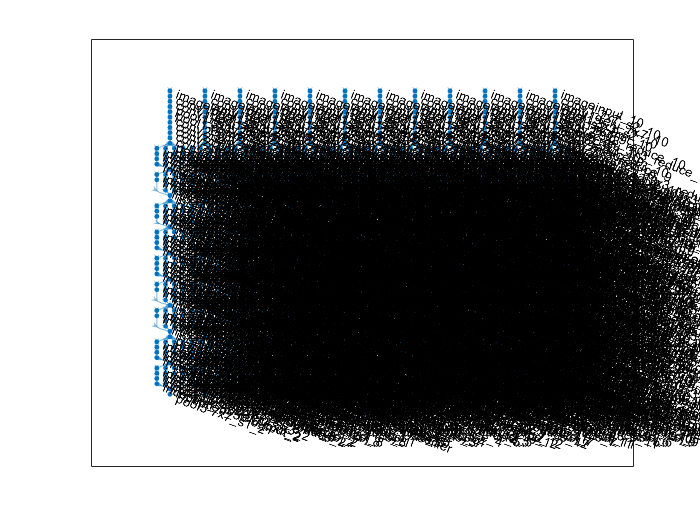

plot(lgraph);

##  Plot Layers

plot(lgraph);

dlnet = dlnetwork(lgraph); % A dlnetwork object enables support for custom training loops using automatic differentiation

Layers = dlnet.Layers

Layers =   1684×1 Layer array with layers:

     1   'imageinput_2'                      Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2_2'                    Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7_2'                  ReLU                          ReLU
     4   'pool1-3x3_s2_2'                    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1_2'                     Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce_2'                Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce_2'           ReLU                          ReLU
     8   'conv2-3x3_2'                       C



miniBatchSize = 4; % mini batch size. When you run out of memory, decrease this value like 4 
numEpochs = 5; % max epoch
numObservations = numel(YTrain); % the number of training data
numIterationsPerEpoch = floor(numObservations./miniBatchSize); % number of iterations per epoch

Initial setting for `Adam` optimizer

averageGrad = [];
averageSqGrad = [];
iteration = 1; % initialize iteration

if canUseGPU
    executionEnvironment = "gpu";
    numberOfGPUs = gpuDeviceCount("available");
    pool = parpool(numberOfGPUs);
else
    executionEnvironment = "cpu";
    pool = parpool;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 1).


## Create `animated line`

`animatedline` creates an animated line that has no data and adds it to the current axes. Create an animation by adding points to the line in a loop using the `addpoints` function.

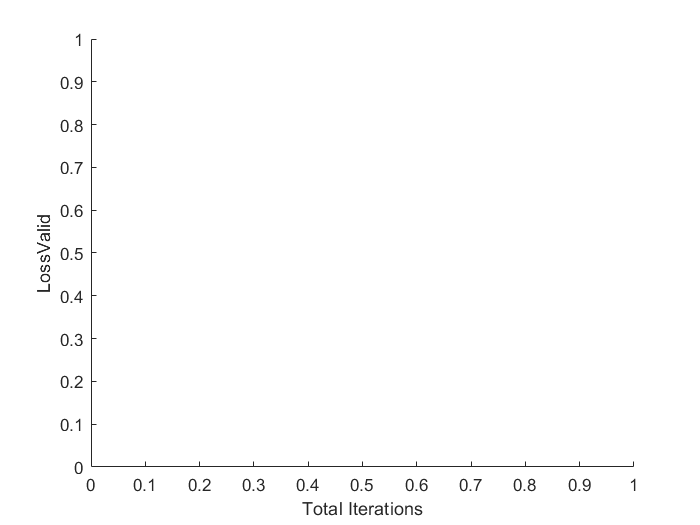

plots = "training-progress";
if plots == "training-progress"
    f1=figure;
    lineLossTrain = animatedline('Color','r');
    xlabel("Total Iterations")
    ylabel("Loss");lineLossValid = animatedline('Color','b');
    xlabel("Total Iterations");ylabel("LossValid")
end

## Prepare the validation data

The validation data is called during training to check the CNN performance. 

YValidPlot=zeros(numClasses,numel(YValid),'single');
for c = 1:numClasses
    YValidPlot(c,YValid==classes(c)) = 1;
end
% Convert mini-batch of data to a dlarray.
dlXValidavf=dlarray(single(XValidavf),'SSCB');
dlXValidavl=dlarray(single(XValidavl),'SSCB');
dlXValidavr=dlarray(single(XValidavr),'SSCB');
dlXValidi=dlarray(single(XValidi),'SSCB');
dlXValidii=dlarray(single(XValidii),'SSCB');
dlXValidiii=dlarray(single(XValidiii),'SSCB');
dlXValidv1=dlarray(single(XValidv1),'SSCB');
dlXValidv2=dlarray(single(XValidv2),'SSCB');
dlXValidv3=dlarray(single(XValidv3),'SSCB');
dlXValidv4=dlarray(single(XValidv4),'SSCB');
dlXValidv5=dlarray(single(XValidv5),'SSCB');
dlXValidv6=dlarray(single(XValidv6),'SSCB');

% If training on a GPU, then convert data to a gpuArray.
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlXValidavf = gpuArray(dlXValidavf);
    dlXValidavl = gpuArray(dlXValidavl);
    dlXValidavr = gpuArray(dlXValidavr);
    dlXValidi = gpuArray(dlXValidi);
    dlXValidii = gpuArray(dlXValidii);
    dlXValidiii = gpuArray(dlXValidiii);
    dlXValidv1 = gpuArray(dlXValidv1);
    dlXValidv2 = gpuArray(dlXValidv2);
    dlXValidv3 = gpuArray(dlXValidv3);
    dlXValidv4 = gpuArray(dlXValidv4);
    dlXValidv5 = gpuArray(dlXValidv5);
    dlXValidv6 = gpuArray(dlXValidv6);
end

## Train network in custom training loop

for epoch = 1:numEpochs
    % Shuffle data.
    idx = randperm(numel(YTrain));
    XTrainavf = XTrainavf(:,:,:,idx);
    XTrainavl = XTrainavl(:,:,:,idx);
    XTrainavr = XTrainavr(:,:,:,idx);
    XTraini = XTraini(:,:,:,idx);
    XTrainii = XTrainii(:,:,:,idx);
    XTrainiii = XTrainiii(:,:,:,idx);
    XTrainv1 = XTrainv1(:,:,:,idx);
    XTrainv2 = XTrainv2(:,:,:,idx);
    XTrainv3 = XTrainv3(:,:,:,idx);
    XTrainv4 = XTrainv4(:,:,:,idx);
    XTrainv5 = XTrainv5(:,:,:,idx);
    XTrainv6 = XTrainv6(:,:,:,idx);
    
    YTrain=YTrain(idx);
    
    for i = 1:numIterationsPerEpoch
        
        % Read mini-batch of data and convert the labels to dummy
        % variables.
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        Xavf = XTrainavf(:,:,:,idx);
        Xavl = XTrainavl(:,:,:,idx);
        Xavr = XTrainavr(:,:,:,idx);
        Xi = XTraini(:,:,:,idx);
        Xii = XTrainii(:,:,:,idx);
        Xiii = XTrainiii(:,:,:,idx);
        Xv1 = XTrainv1(:,:,:,idx);
        Xv2 = XTrainv2(:,:,:,idx);
        Xv3 = XTrainv3(:,:,:,idx);
        Xv4 = XTrainv4(:,:,:,idx);
        Xv5 = XTrainv5(:,:,:,idx);
        Xv6 = XTrainv6(:,:,:,idx);
   
        
        Y = zeros(numClasses, miniBatchSize, 'single');
        for c = 1:numClasses
            Y(c,YTrain(idx)==classes(c)) = 1;
        end
        
        % Convert mini-batch of data to a dlarray.
        
        dlXavf = dlarray(single(Xavf),'SSCB');
        dlXavl = dlarray(single(Xavl),'SSCB');
        dlXavr = dlarray(single(Xavr),'SSCB');
        dlXi = dlarray(single(Xi),'SSCB');
        dlXii = dlarray(single(Xii),'SSCB');
        dlXiii = dlarray(single(Xiii),'SSCB');
        dlXv1 = dlarray(single(Xv1),'SSCB');
        dlXv2 = dlarray(single(Xv2),'SSCB');
        dlXv3 = dlarray(single(Xv3),'SSCB');
        dlXv4 = dlarray(single(Xv4),'SSCB');
        dlXv5 = dlarray(single(Xv5),'SSCB');
        dlXv6 = dlarray(single(Xv6),'SSCB');
        
        % If training on a GPU, then convert data to a gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlXavf = gpuArray(dlXavf);
            dlXavl = gpuArray(dlXavl);
            dlXavr = gpuArray(dlXavr);
            dlXi = gpuArray(dlXi);
            dlXii = gpuArray(dlXii);
            dlXiii = gpuArray(dlXiii);
            dlXv1 = gpuArray(dlXv1);
            dlXv2 = gpuArray(dlXv2);
            dlXv3 = gpuArray(dlXv3);
            dlXv4 = gpuArray(dlXv4);
            dlXv5 = gpuArray(dlXv5);
            dlXv6 = gpuArray(dlXv6);
            
        end
        
        % Evaluate the model gradients and loss using dlfeval and the
        % modelGradients helper function.
        [grad,loss] = dlfeval(@modelGradientsMulti,dlnet,dlXavf,dlXavl,dlXavr,dlXi,dlXii,dlXiii,dlXv1,dlXv2,dlXv3,dlXv4,dlXv5,dlXv6,Y);
        lossValid = modelLossMulti(dlnet,dlXValidavf,dlXValidavl,dlXValidavr,dlXValidi,dlXValidii,dlXValidiii,dlXValidv1,dlXValidv2,dlXValidv3,dlXValidv4,dlXValidv5,dlXValidv6,YValidPlot);
        % Update the network parameters using the Adam optimizer.
        [dlnet,averageGrad,averageSqGrad] = adamupdate(dlnet,grad,averageGrad,averageSqGrad,iteration,0.0005);
        
        % Display the training progress.
        if plots == "training-progress"
            addpoints(lineLossTrain,iteration,double(gather(extractdata(loss))))
            title("Loss During Training: Epoch - " + epoch + "; Iteration - " + i)
            addpoints(lineLossValid,iteration,double(gather(extractdata(lossValid))))
            title("Loss During Validation: Epoch - " + epoch + "; Iteration - " + i)
            drawnow
        end
        
        % Increment the iteration counter.
        iteration = iteration + 1;
    end
end

## Compute classification accuracy 

dlXTestavf = dlarray(single(XTestavf),'SSCB');
dlXTestavl = dlarray(single(XTestavl),'SSCB');
dlXTestavr = dlarray(single(XTestavr),'SSCB');
dlXTesti = dlarray(single(XTesti),'SSCB');
dlXTestii = dlarray(single(XTestii),'SSCB');
dlXTestiii = dlarray(single(XTestiii),'SSCB');
dlXTestv1 = dlarray(single(XTestv1),'SSCB');
dlXTestv2 = dlarray(single(XTestv2),'SSCB');
dlXTestv3 = dlarray(single(XTestv3),'SSCB');
dlXTestv4 = dlarray(single(XTestv4),'SSCB');
dlXTestv5 = dlarray(single(XTestv5),'SSCB');
dlXTestv6 = dlarray(single(XTestv6),'SSCB');


Convert the test data into `gpuArray` to accelarate with GPU

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlXTestavf = gpuArray(dlXTestavf);
    dlXTestavl = gpuArray(dlXTestavl);
    dlXTestavr = gpuArray(dlXTestavr);
    dlXTesti = gpuArray(dlXTesti);
    dlXTestii = gpuArray(dlXTestii);
    dlXTestiii = gpuArray(dlXTestiii);
    dlXTestv1 = gpuArray(dlXTestv1);
    dlXTestv2 = gpuArray(dlXTestv2);
    dlXTestv3 = gpuArray(dlXTestv3);
    dlXTestv4 = gpuArray(dlXTestv4);
    dlXTestv5 = gpuArray(dlXTestv5);
    dlXTestv6 = gpuArray(dlXTestv6);
    
end

Two similar function are available in MATLAB for calculating the output of deep learning network. 

`predict`: Compute deep learning network output for inference

`forward`: Compute deep learning network output for training

The difference is either for training or testing. In the training phase, some techniques like batch normalization and dropout are employed while they are not used in testing.

dlYPred = predict(dlnet,dlXTestavf,dlXTestavl,dlXTestavr,dlXTesti,dlXTestii,dlXTestiii,dlXTestv1,dlXTestv2,dlXTestv3,dlXTestv4,dlXTestv5,dlXTestv6); % use predict for testing
[~,idx] = max(extractdata(dlYPred),[],1); % extract the class with highest score
YPred = classes(idx);

Calculate the overall accuracy

accuracy = mean(YPred==YTest)

accuracy = 0.4667

Display confusion matrix 

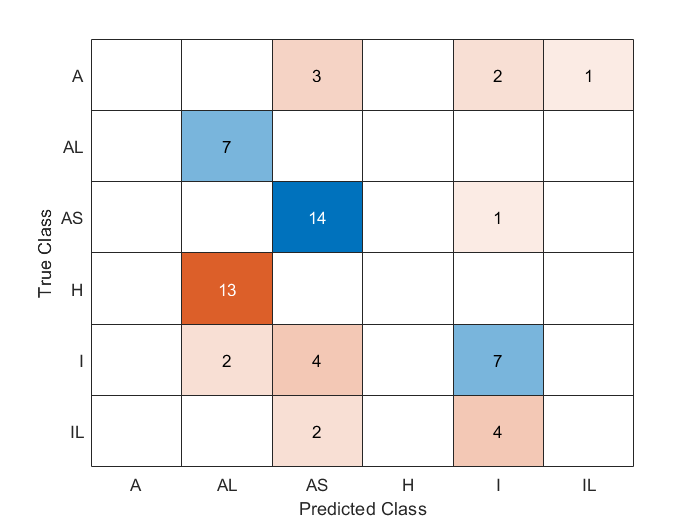

confusionchart(YTest,categorical(cellstr(YPred)))

## Helper functions

function [gradients,loss] = modelGradientsMulti(dlnet,dlXavf,dlXavl,dlXavr,dlXi,dlXii,dlXiii,dlXv1,dlXv2,dlXv3,dlXv4,dlXv5,dlXv6,Y)

    dlYPred = forward(dlnet,dlXavf,dlXavl,dlXavr,dlXi,dlXii,dlXiii,dlXv1,dlXv2,dlXv3,dlXv4,dlXv5,dlXv6);
    dlYPred = softmax(dlYPred);
    
    loss = crossentropy(dlYPred,Y);
    gradients = dlgradient(loss,dlnet.Learnables);

end



function loss = modelLossMulti(dlnet,dlXavf,dlXavl,dlXavr,dlXi,dlXii,dlXiii,dlXv1,dlXv2,dlXv3,dlXv4,dlXv5,dlXv6,Y)
    dlYPred = forward(dlnet,dlXavf,dlXavl,dlXavr,dlXi,dlXii,dlXiii,dlXv1,dlXv2,dlXv3,dlXv4,dlXv5,dlXv6);
    dlYPred = softmax(dlYPred);
    loss = crossentropy(dlYPred,Y);
end

